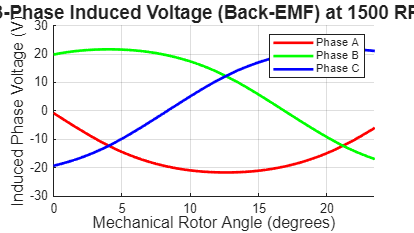

%% ------------------------------------------------------------------------
% ROBUST 3-PHASE BACK-EMF CALCULATION FROM COMSOL EXPORT
% ------------------------------------------------------------------------
clear; clc; close all;

% 1. Load the data. readmatrix automatically ignores the '%' header lines.
% Make sure your file is exactly named 'flux_data.txt' and is in your current folder.
data = readmatrix('flux_data.txt');

% 2. Clean the data (remove any rows that imported as NaN due to empty lines)
data(any(isnan(data), 2), :) = [];

% Extract the raw columns
theta_all = data(:, 1);
flux_all = data(:, 2);

% 3. Dynamically separate the 3 phases
% COMSOL resets the angle back to 0 at the start of each phase.
% We can find these exact reset points by looking for where the angle drops (diff < 0).
split_points = find(diff(theta_all) < 0);

if length(split_points) >= 2
    idx1 = split_points(1);
    idx2 = split_points(2);
else
    error('Could not find 3 distinct phases. Ensure the file contains Phase A, B, and C.');
end

% Extract the individual phases based on the detected split points
theta_rad = theta_all(1:idx1);
flux_A = flux_all(1:idx1);
flux_B = flux_all(idx1+1:idx2);
flux_C = flux_all(idx2+1:end);

% Ensure all vectors are exactly the same length before doing math
min_len = min([length(flux_A), length(flux_B), length(flux_C)]);
theta_rad = theta_rad(1:min_len);
flux_A = flux_A(1:min_len);
flux_B = flux_B(1:min_len);
flux_C = flux_C(1:min_len);

% 4. Physics Parameters
n_rpm = 1500;
w_m = n_rpm * (2*pi/60); % Mechanical speed in rad/s

% Convert angle to degrees for a nice X-axis on the plot
% We use 1:end-1 because taking the derivative makes the array 1 data point shorter
theta_plot_deg = rad2deg(theta_rad(1:end-1)); 

% Calculate dTheta (in radians)
dTheta = diff(theta_rad);

% 5. Apply Faraday's Law using the Chain Rule: E = - (dPhi/dTheta) * w_m
V_phaseA = - (diff(flux_A) ./ dTheta) * w_m;
V_phaseB = - (diff(flux_B) ./ dTheta) * w_m;
V_phaseC = - (diff(flux_C) ./ dTheta) * w_m;

% --- PLOT THE 3-PHASE BACK-EMF ---
figure('Name', '3-Phase Back-EMF', 'Color', 'w', 'Position', [100, 100, 800, 450]);
hold on; grid on;
plot(theta_plot_deg, V_phaseA, 'r-', 'LineWidth', 2, 'DisplayName', 'Phase A');
plot(theta_plot_deg, V_phaseB, 'g-', 'LineWidth', 2, 'DisplayName', 'Phase B');
plot(theta_plot_deg, V_phaseC, 'b-', 'LineWidth', 2, 'DisplayName', 'Phase C');

title('3-Phase Induced Voltage (Back-EMF) at 1500 RPM', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Mechanical Rotor Angle (degrees)', 'FontSize', 12);
ylabel('Induced Phase Voltage (V)', 'FontSize', 12);
legend('Location', 'northeast');
xlim([0, max(theta_plot_deg)]);


% Find and display the peak voltage
peak_V = max(abs(V_phaseA));
fprintf('Simulated Peak Phase Voltage: %.2f V\n', peak_V);

Simulated Peak Phase Voltage: 21.66 V
